## I- Plot XY data

## (1) Simple data plotting

help plot

 plot   Linear plot. 
    plot(X,Y) plots vector Y versus vector X. If X or Y is a matrix,
    then the vector is plotted versus the rows or columns of the matrix,
    whichever line up.  If X is a scalar and Y is a vector, disconnected
    line objects are created and plotted as discrete points vertically at
    X.
 
    plot(Y) plots the columns of Y versus their index.
    If Y is complex, plot(Y) is equivalent to plot(real(Y),imag(Y)).
    In all other uses of plot, the imaginary part is ignored.
 
    Various line types, plot symbols and colors may be obtained with
    plot(X,Y,S) where S is a character string made from one element
    from any or all the following 3 columns:
 
           b     blue          .     point              -     solid
           g     green         o     circle             :     dotted
           r     red           x     x-mark         

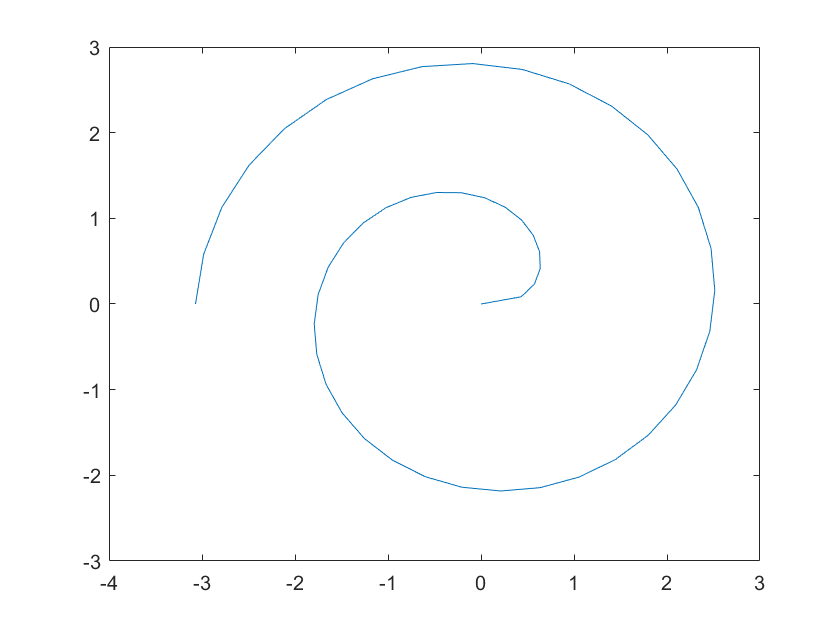

%30 points between 0 and 3pi
t = linspace(0,3*pi,50); 
x = sqrt(t).*cos(t);
y = sqrt(t).*sin(t);
figure %new figure window
plot(x,y)

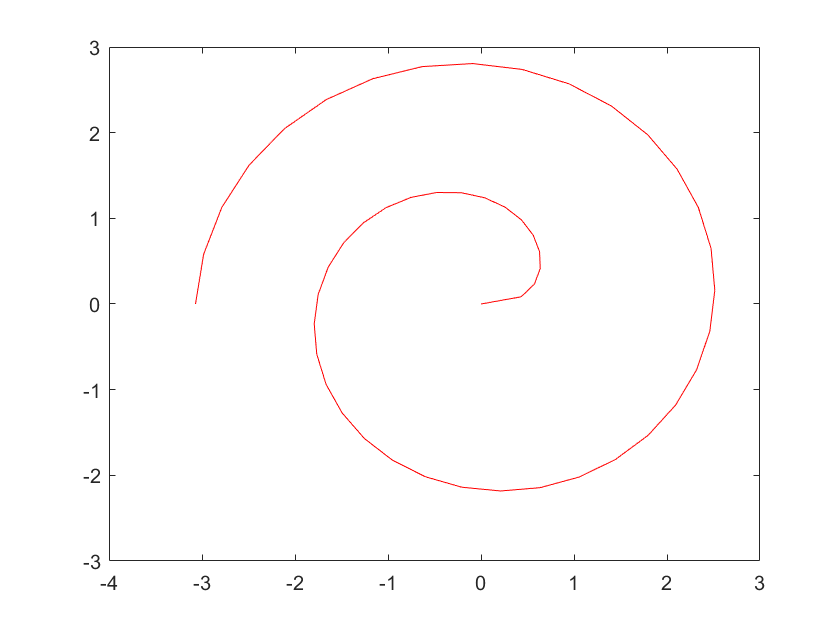

%plot x,y data in red
plot(x,y,'r') 

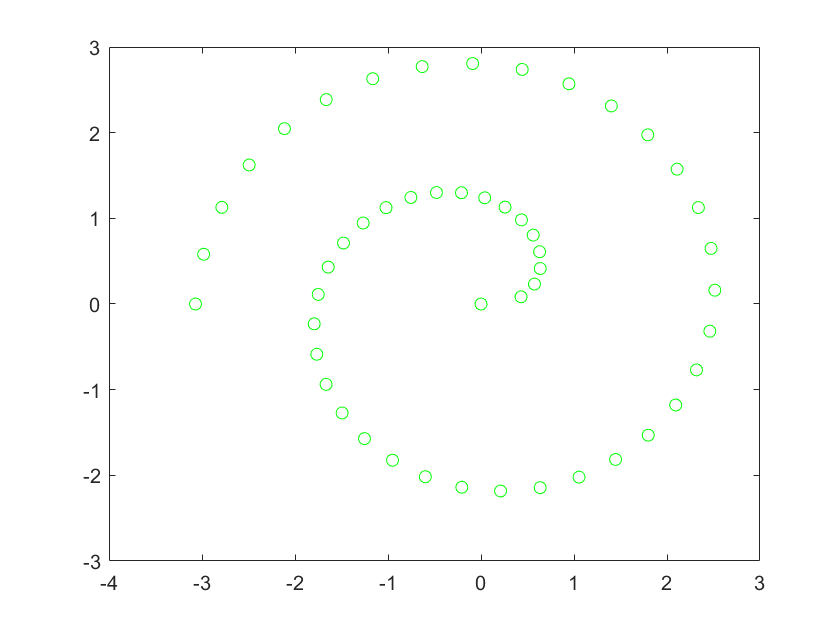

%plot x,y data in green as open circles
plot(x,y,'og') 

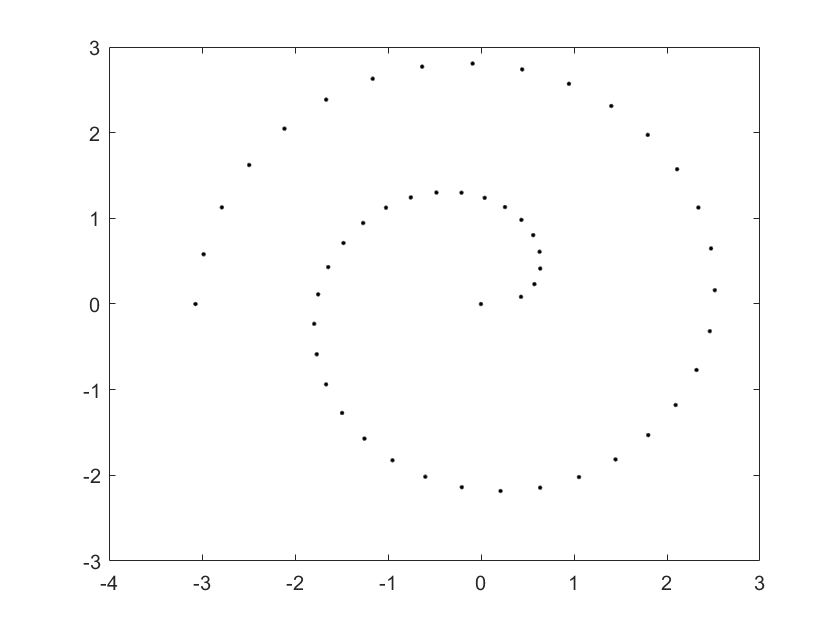

%plot x,y data in black as points
plot(x,y,'.k') 

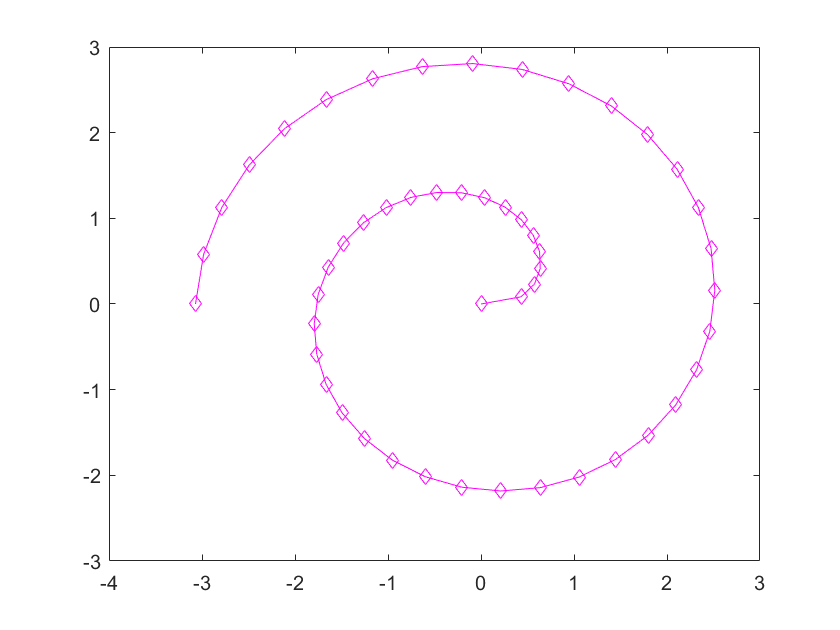

%color: magenta as diamonds with solid line
plot(x,y,'dm-') 

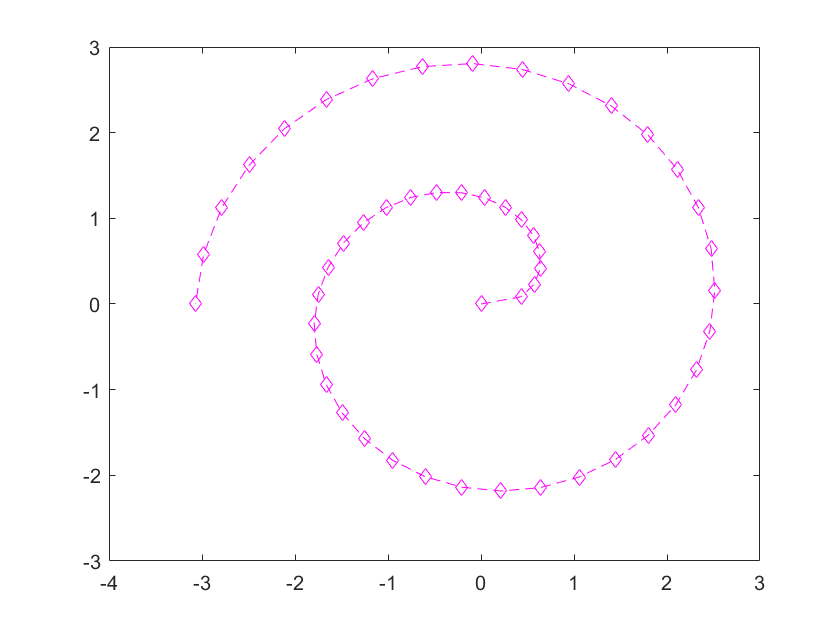

%color: magenta as diamonds with dashed line
plot(x,y,'dm--') 

## (2) using set to manipulate figure using handles

we can use handles to change plot properties

%output the handle as h
h=plot(x,y,'dm--'); 

% getting information of the plot handle
get(h);

    AlignVertexCenters: 'off'
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: 'off'
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: 'on'
                 Color: [1 0 1]
             ColorMode: 'manual'
             CreateFcn: ''
       DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: 'on'
         Interruptible: 'on'
              LineJoin: 'round'
             LineStyle: '--'
         LineStyleMode: 'manual'
             LineWidth: 0.5000
                Marker: 'diamond'
       MarkerEdgeColor: 'auto'
       MarkerFaceColor: 'none'
         MarkerIndices: [1×50 uint64]
            MarkerMode: 'manual'
            MarkerSize: 6
                Parent: [1×1 Axes]
         PickableParts: 'visible'
              Selected: 'off'
    SelectionHi

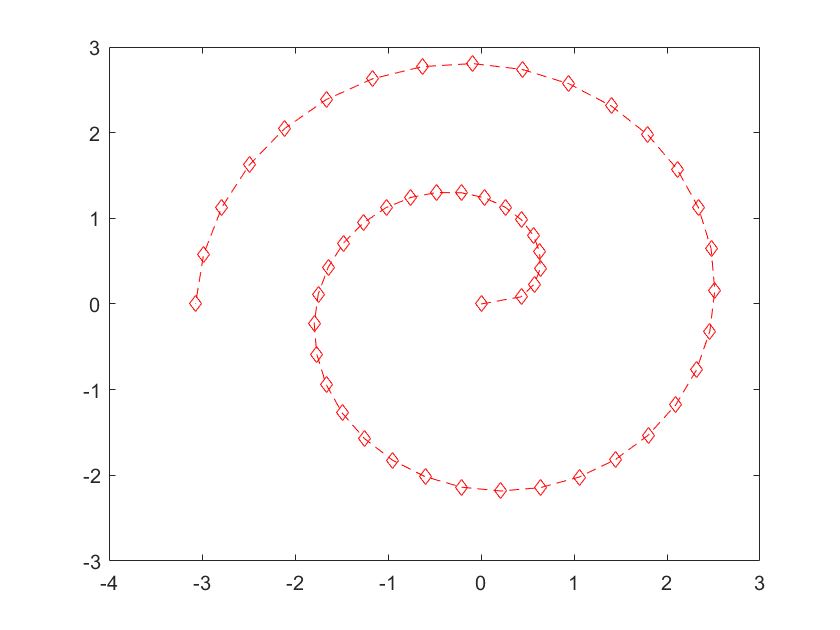

%set the color to red
set(h,'color',[1 0 0])

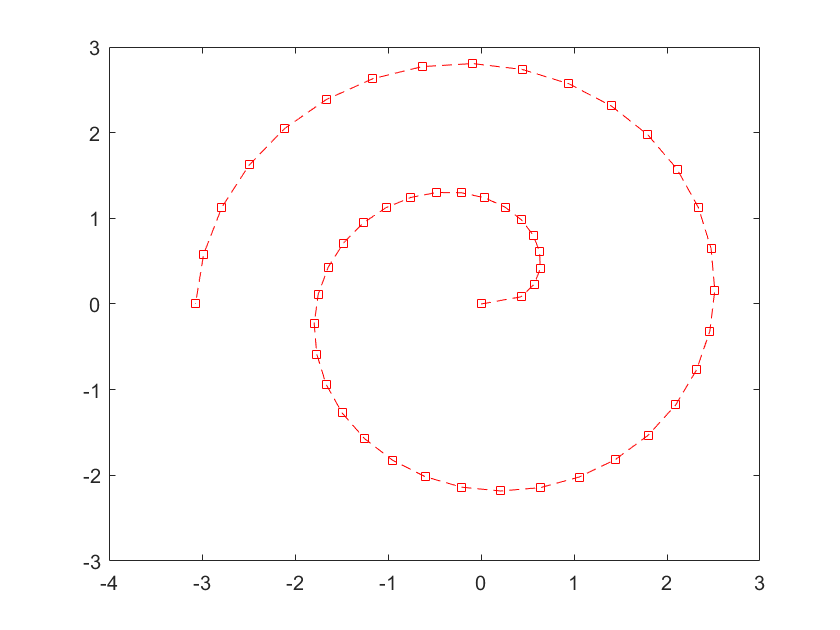

%set the symbols as squares
set(h,'marker','square') 

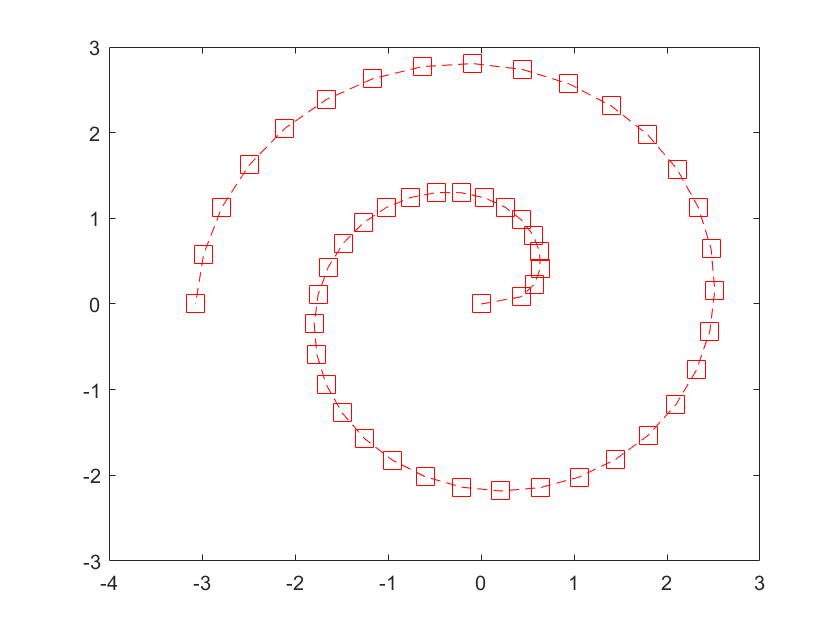

%set the symbol size to 12 pts
set(h,'markersize',12) 

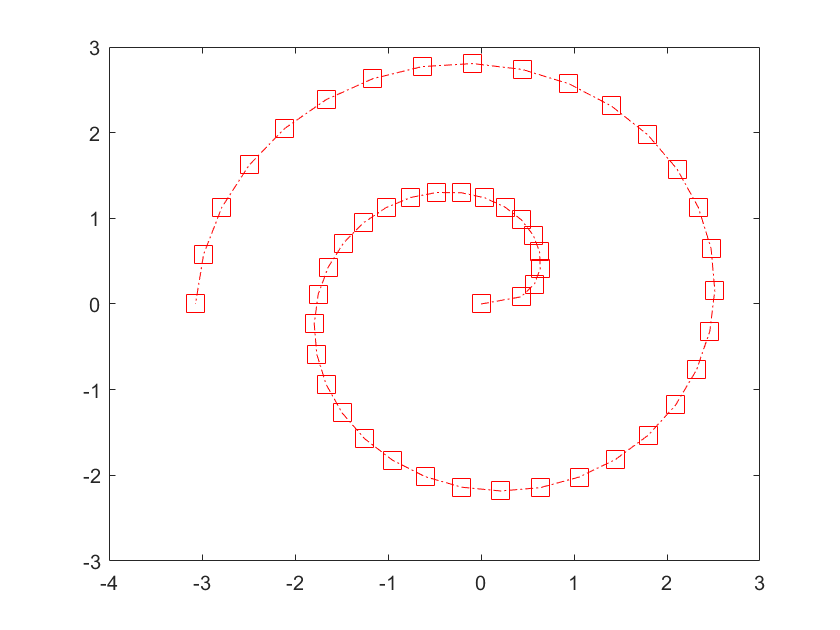

%set the line to dot-dashed
set(h,'linestyle','-.') 

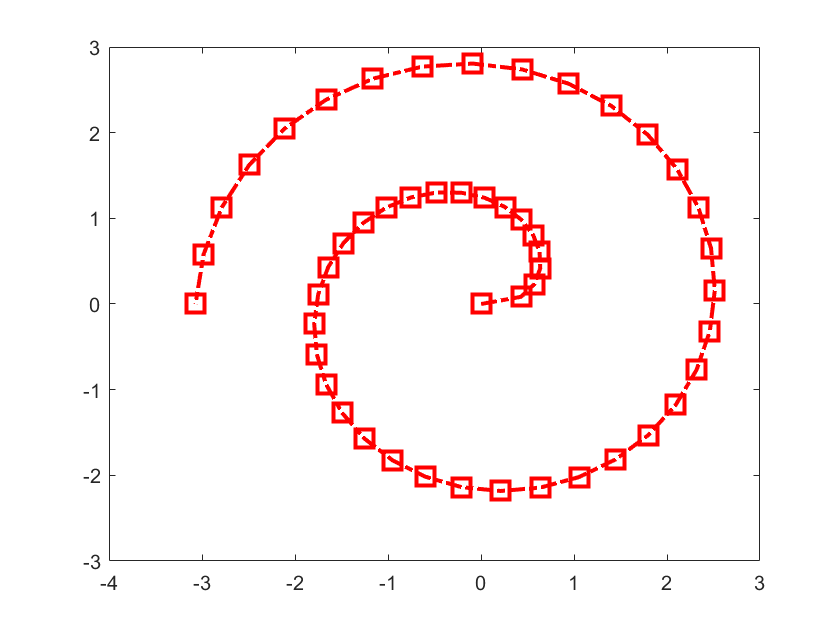

%set the line thickness to 2pts
set(h,'LineWidth',2)

## (3) generate second data set and add into plot

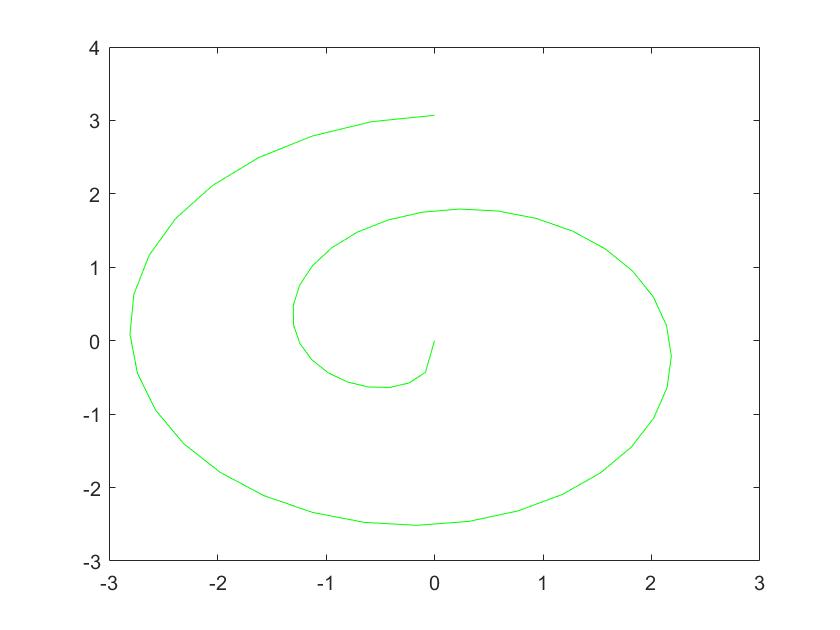

h1 =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×50 double]
              YData: [1×50 double]
              ZData: [1×0 double]

  Show all properties


%create a new x1 array
x1 = -y; 
%new y1 array
y1 = -x; 
%create a new plot handle h1
h1 = plot(x1,y1,'g') 

## (4) using Hold on

% new handle h0 with black color for line properties
h0 = plot(x,y,'k') 

h0 =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×50 double]
              YData: [1×50 double]
              ZData: [1×0 double]

  Show all properties


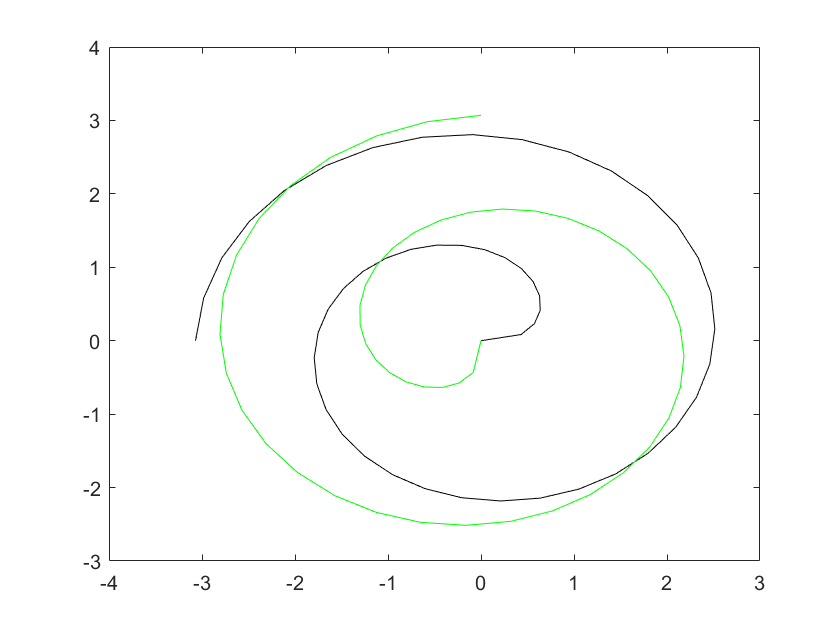

h1 =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×50 double]
              YData: [1×50 double]
              ZData: [1×0 double]

  Show all properties


hold on
%create and plot new handle h1
h1 = plot(x1,y1,'g') 

## (5) Modifying the axes using gca

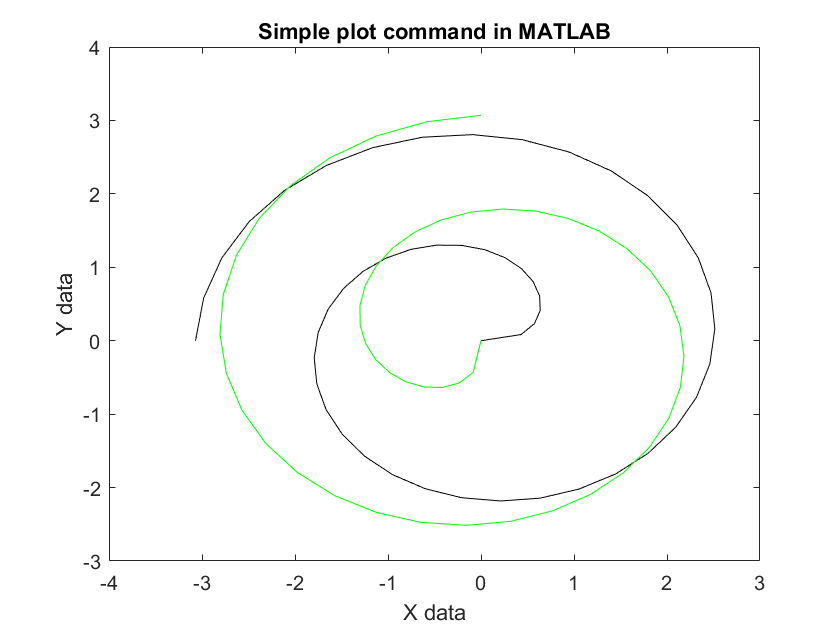

%add a text string to the x-axis
xlabel('X data')
%add y axis label
ylabel('Y data') 
%add a title
title('Simple plot command in MATLAB') 

%getting handle for axes
get(gca)

                       ALim: [0 1]
                   ALimMode: 'auto'
     ActivePositionProperty: 'outerposition'
                 AlphaScale: 'linear'
                   Alphamap: [1×64 double]
          AmbientLightColor: [1 1 1]
               BeingDeleted: 'off'
                        Box: 'on'
                   BoxStyle: 'back'
                 BusyAction: 'queue'
              ButtonDownFcn: ''
                       CLim: [0 1]
                   CLimMode: 'auto'
             CameraPosition: [1×3 double]
         CameraPositionMode: 'auto'
               CameraTarget: [1×3 double]
           CameraTargetMode: 'auto'
             CameraUpVector: [0 1 0]
         CameraUpVectorMode: 'auto'
            CameraViewAngle: 6.6086
        CameraViewAngleMode: 'auto'
                   Children: [2×1 Line]
                   Clipping: 'on'
              ClippingStyle: '3dbox'
                      Color: [1 1 1]
                 ColorOrder: [7×3 double]
            ColorOrderIndex: 3

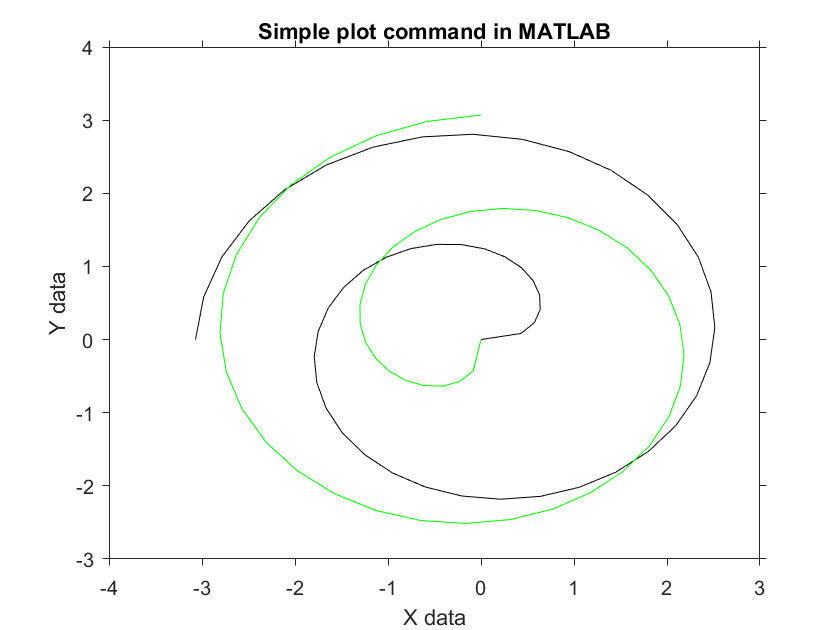

%setting handle for axes
%tick marks point outwards instead of inwards
set(gca,'tickdir','out') 

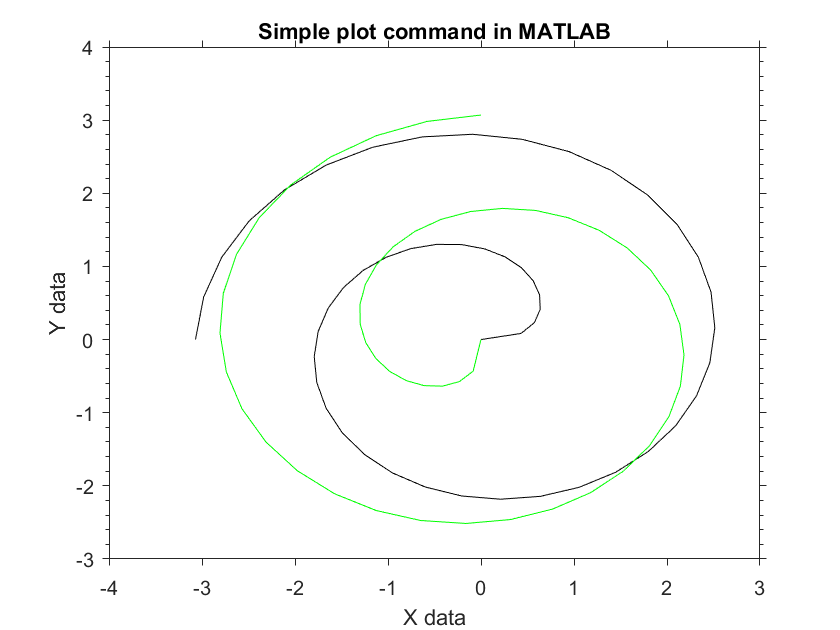

%plot intermediate ticks on the y-axis
set(gca,'yminortick','on') 

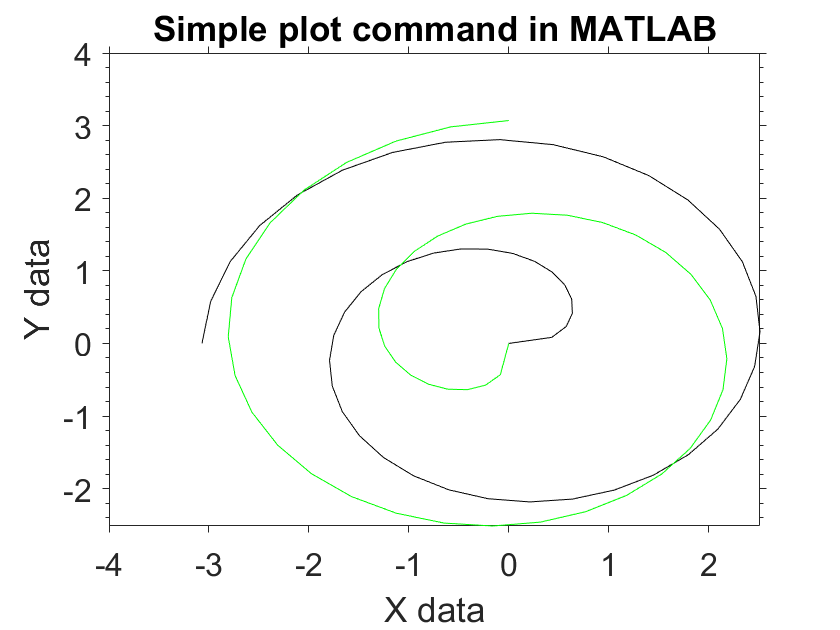

%set the text size to 16 points
set(gca,'fontsize',16) 

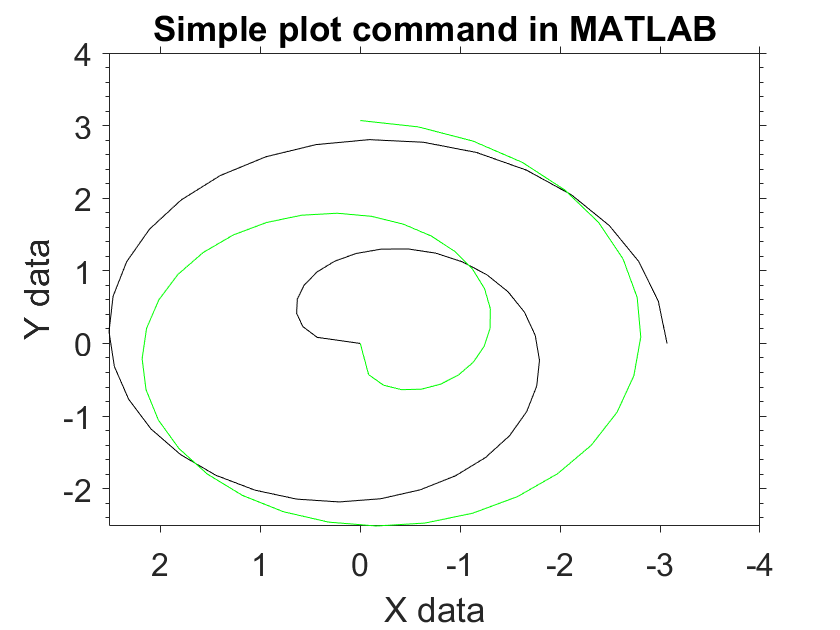

%reverse the direction of the x-axis
set(gca,'xdir','reverse') 

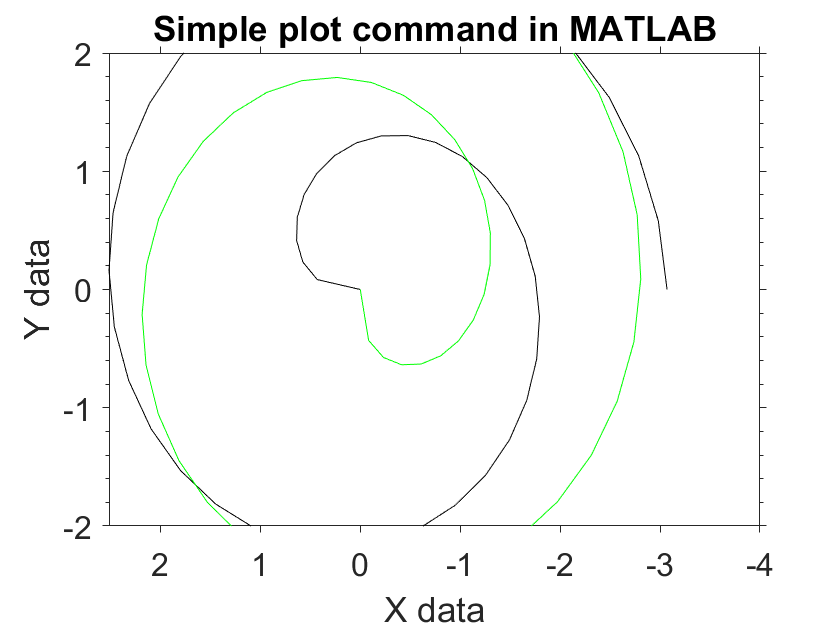

%set the y-axis range as -2 to 2
set(gca,'ylim',[-2 2]) 

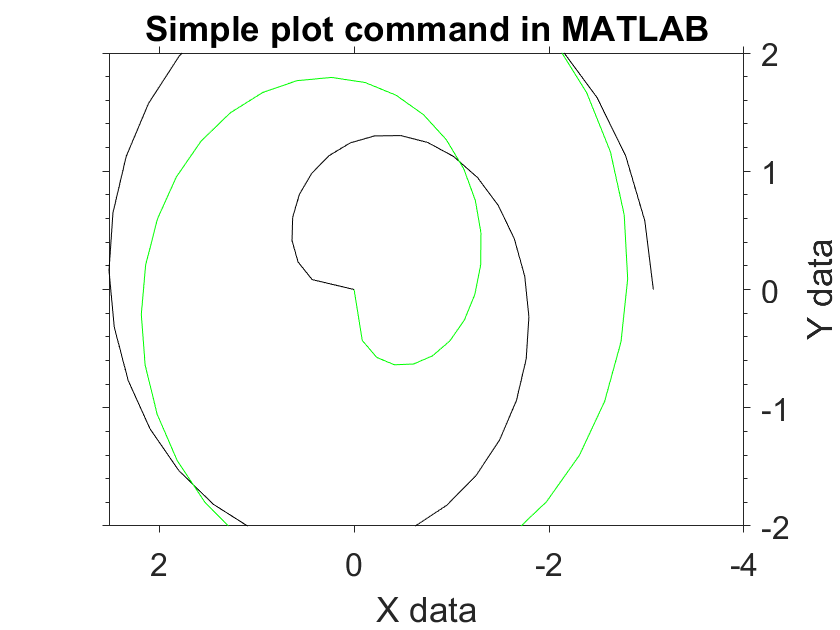

%place the y-axis on the right hand side
set(gca,'yaxislocation','right') 

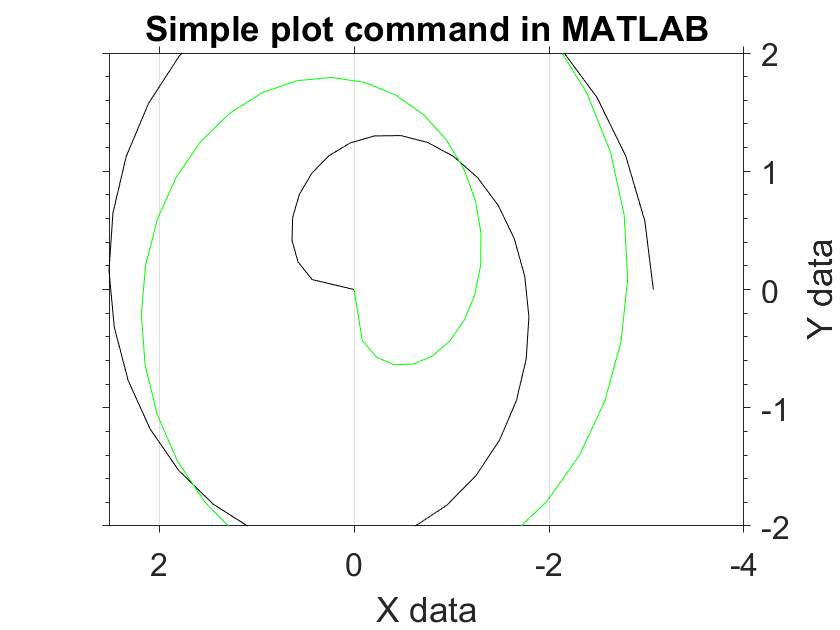

%plot a grid over the x-axis
set(gca,'xgrid','on') 

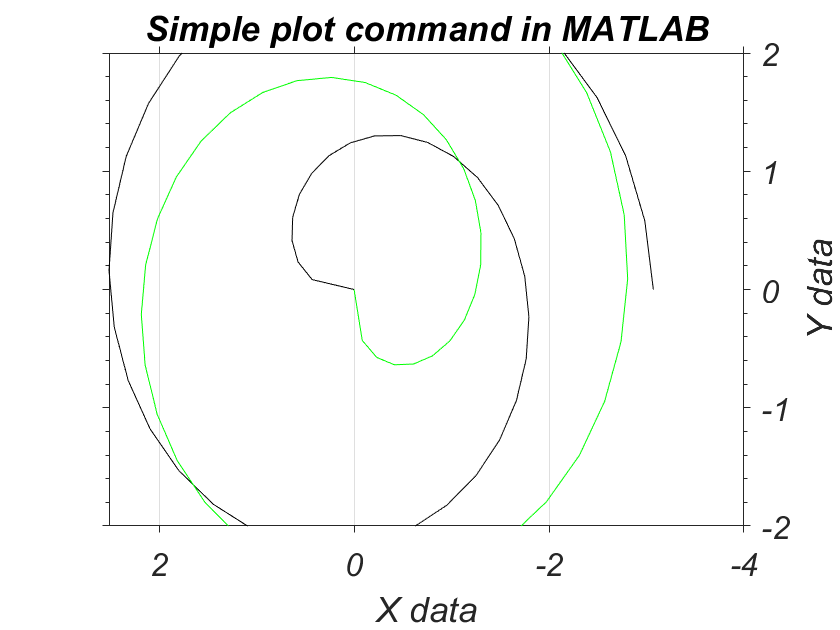

%use italic fonts
set(gca,'fontangle','italic') 

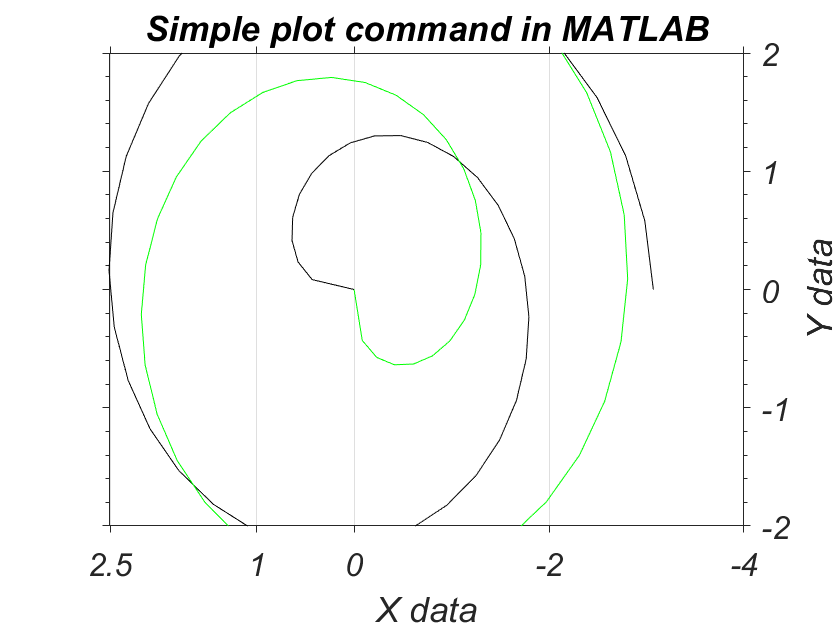

%plot xticks at specific values
set(gca,'xtick',[-4 -2 0 1 2.5 3.7]) 

% So, we can change every aspects using the handles.

## (6) Multiple sets of axes in a single figure

figure %create a new figure window

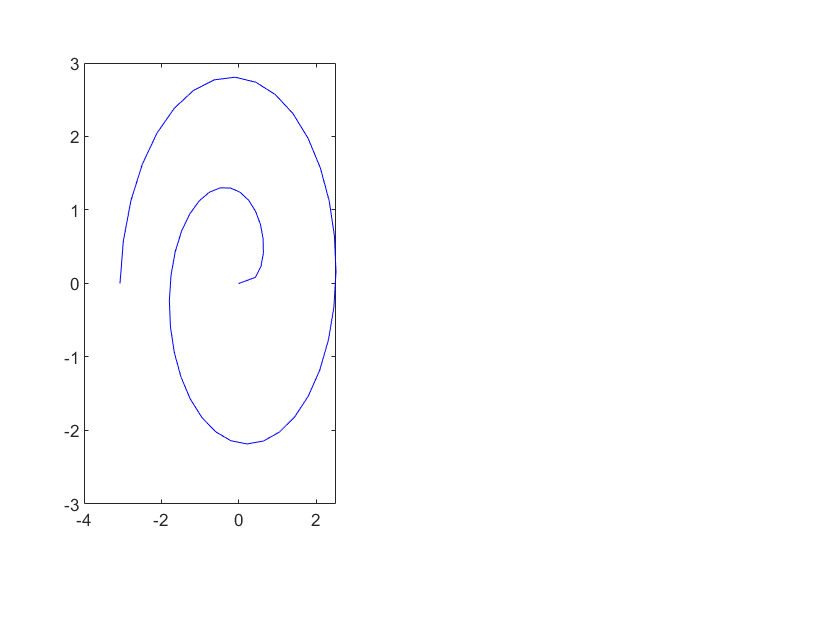

%% for irregular size of figures
% create specific axes
axes('position',[0.1 0.2 0.3 0.7]) 
% [0.1 0.2 0.3 0.7] left, bottom, width, height
plot(x,y,'b') %plot in blue

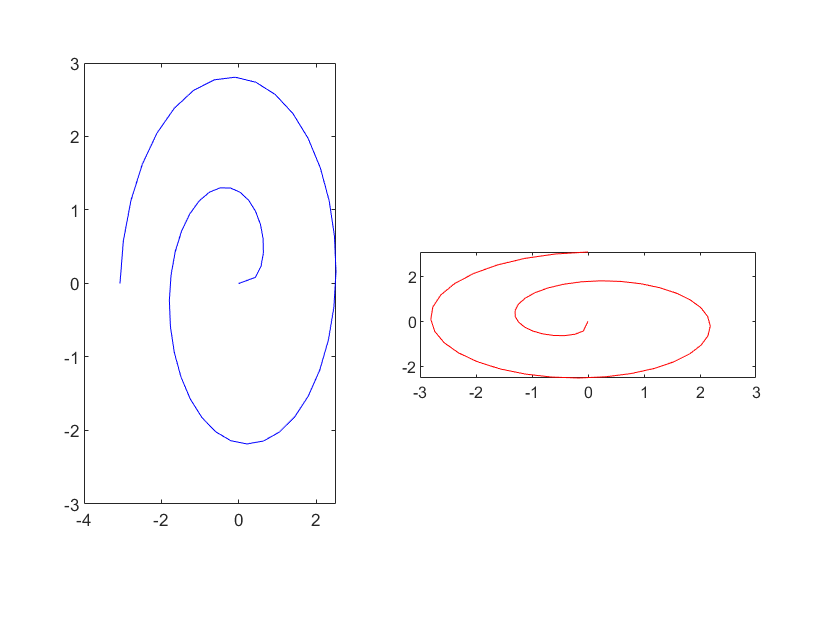

%create specific axes
axes('position',[0.5 0.4 0.4 0.2]) 
plot(x1,y1,'r') %plot x1 and y1 in red

## (7) for regular size of figures using subplot

close all
figure

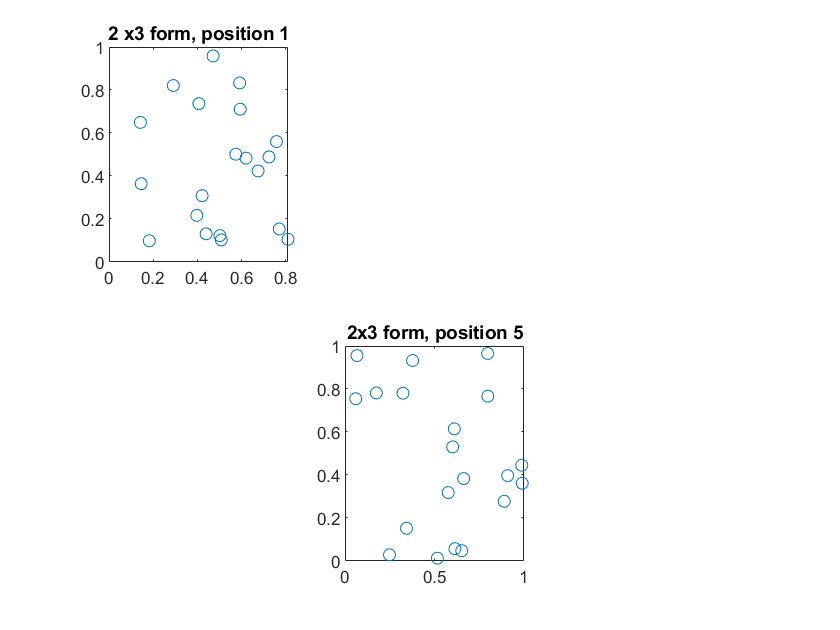

%2rows 3 columns f axes, use position 1
subplot(2,3,1) 
%plot random data
plot(rand(20,1), rand(20,1), 'o') 
title('2 x3 form, position 1')
%2 rows and 3 columns of axes, use position 5
subplot(2,3,5) 
%plot some random data
plot(rand(20,1),rand(20,1),'o') 
title('2x3 form, position 5')

%2 rows & 3 columns of axes, use position 3, return the handle
h3 = subplot(2,3,3) 

h3 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6916 0.5838 0.2134 0.3412]
            Units: 'normalized'

  Show all properties


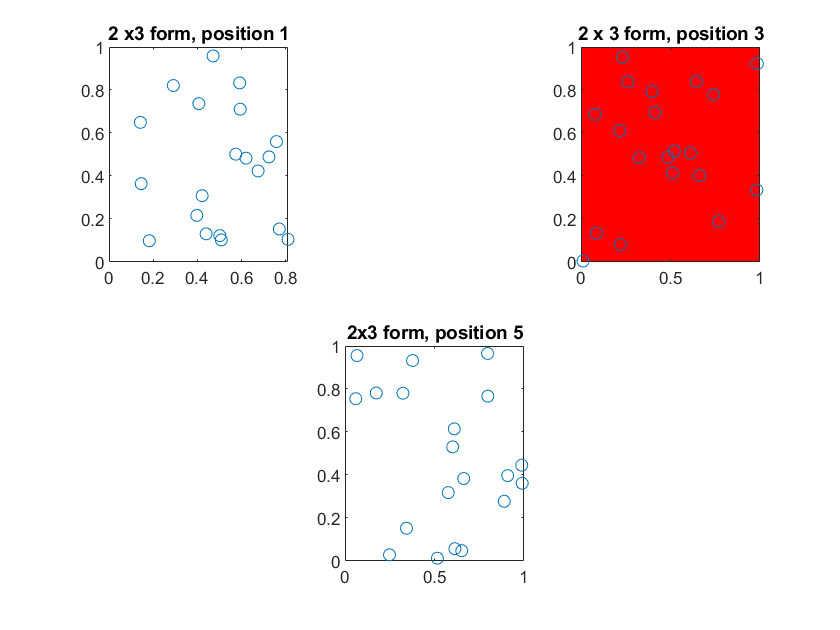

%plot some random data
plot(rand(20,1),rand(20,1),'o') 
title('2 x 3 form, position 3')
%set these axes to be red
set(h3, 'color',[1 0 0]) 

## (8) Different types of plots

%line graphs
help plotyy

help loglog

help semilogx

help semilogy

help stairs

help contour

% Bar Graphs
help barh %grouped

help bar %stacked

help barh %stacked

help hist

help pareto

help errorbar

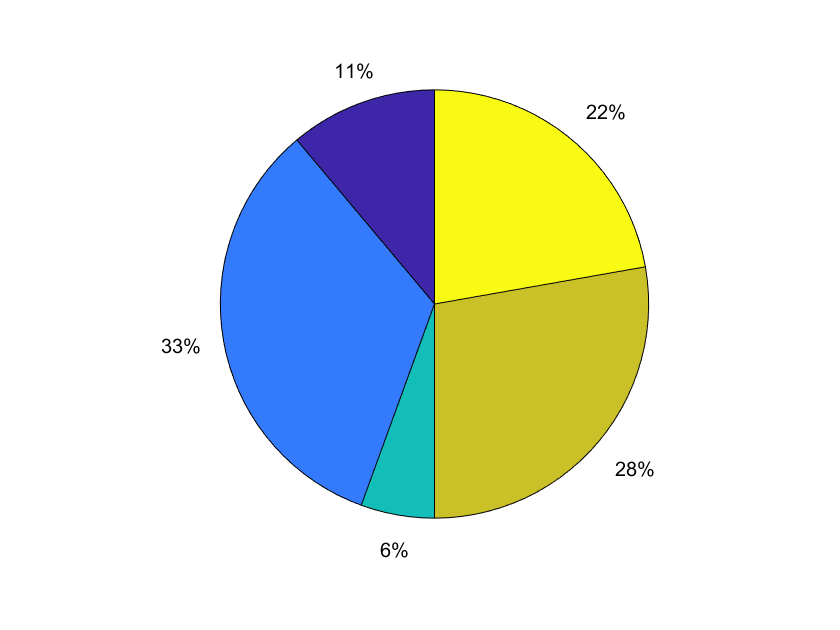

% Area Graphs
close all
hold off
X = [1 3 0.5 2.5 2];
pie(X)

help pie

 pie    Pie chart.
    pie(X) draws a pie chart using the data in X. Each slice of the pie
    chart represents an element in X.
 
       If sum(X)<= 1, then the values in X directly specify the areas of the
       pie slices. pie draws only a partial pie if sum(X) < 1.
 
       If sum(X) > 1, then pie normalizes the values by X/sum(X) to
       determine the area of each slice of the pie.
       
       If X is of data type categorical, the slices correspond to categories.
       Area of each slice is the number of elements in the category divided
       by the number of elements in X. <undefined> elements are ignored.
 
    pie(X,EXPLODE) offsets slices from the pie. explode is a vector or
    matrix of zeros and nonzeros that correspond to X. The pie function
    offsets slices for the nonzero elements only in explode. If X is of
    data type categorical, then explode can be a vector of zeros and
    nonzeros corresponding to categ

doc pie

help fill

help contourf

help image

help pcolor

help ezcontourf

help quiver

% direction graph
help comet

% radial graphs
help rose

help compass

help ezpolar

% Scatter graphs
help spy

help plotmatrix

## (9) Contour plots

clear all, close all
n=20; %number of grid points
[x,y,z]=peaks(n); %evaluate peaks on a 20x20 grid
size(x)

ans =     20    20


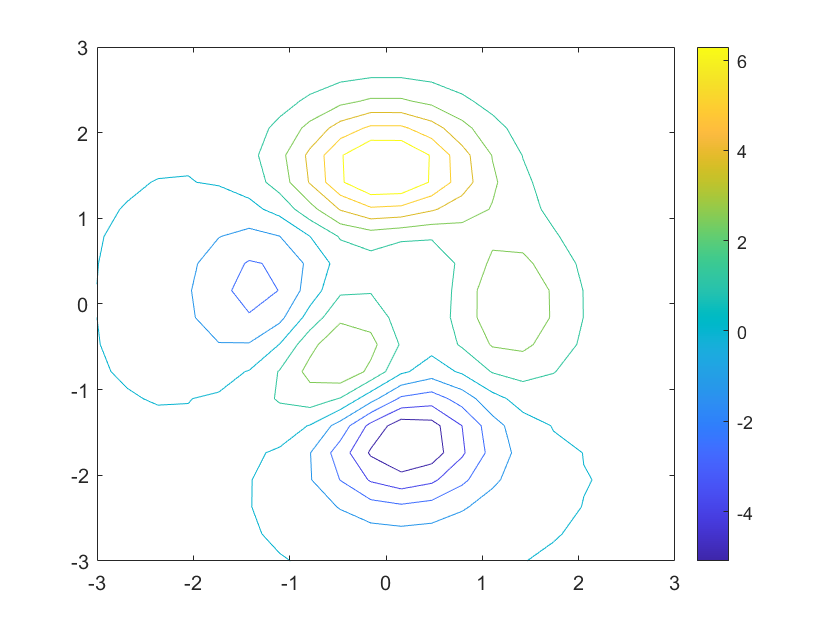

contour(x,y,z,10) %plot with 10 contours
colorbar %add a colorbar to show the z values

clear all, close all
n=4 %number of grid points

n = 4

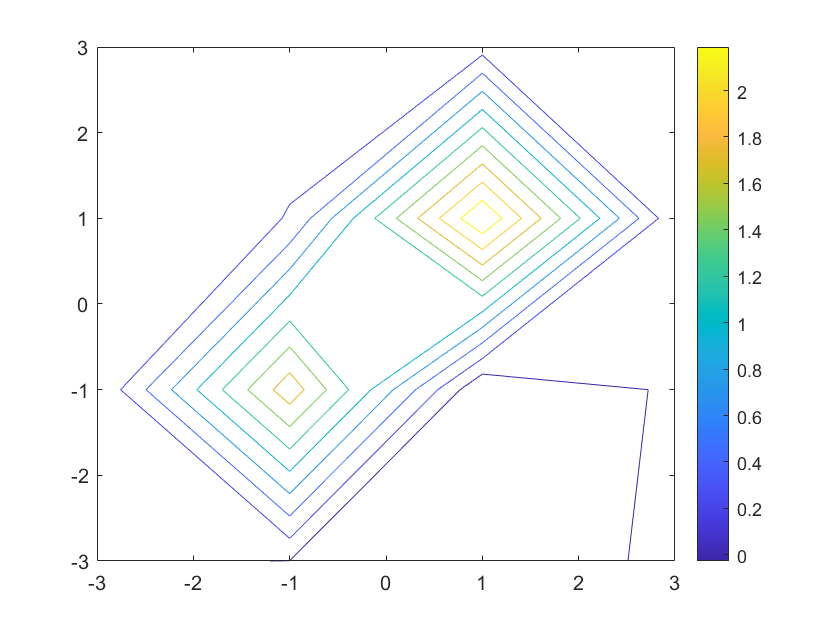

[x,y,z] = peaks(n); %evaluate peaks on a 4x4 grid
contour(x,y,z,10) %plot with 10 contours
colorbar %add a colorbar to show the z values

x

x =     -3    -1     1     3
    -3    -1     1     3
    -3    -1     1     3
    -3    -1     1     3


y

y =     -3    -3    -3    -3
    -1    -1    -1    -1
     1     1     1     1
     3     3     3     3


clear all, close all
x = [4.0 0.5 2.0 0.3 1.2 1.2 0.4 2.2 2.1 2.1 3.1 3.1 4.1 4.5 3.6 5.5 6.0 6.2 6.2 6.2 6.3 6.2 5.6 3.6 4.5 2.5 2.3 1.5 4.5 4.5 5.3 3.5 4.4 3.4 4.8]

x =     4.0000    0.5000    2.0000    0.3000    1.2000    1.2000    0.4000    2.2000    2.1000    2.1000    3.1000    3.1000    4.1000    4.5000    3.6000    5.5000    6.0000    6.2000    6.2000    6.2000    6.3000    6.2000    5.6000    3.6000    4.5000    2.5000    2.3000    1.5000    4.5000    4.5000    5.3000    3.5000    4.4000    3.4000    4.8000


y = [4.0 6.0 5.2 0.3 0.0 0.5 1.0 0.2 0.5 1.1 0.2 1.2 1.2 1.8 2.1 0.5 1.0 1.1 6.1 5.3 4.5 3.4 2.4 2.4 3.2 3.5 3.4 3.5 5.3 5.6 4.3 5.5 6.0 1.8 3.5]

y =     4.0000    6.0000    5.2000    0.3000         0    0.5000    1.0000    0.2000    0.5000    1.1000    0.2000    1.2000    1.2000    1.8000    2.1000    0.5000    1.0000    1.1000    6.1000    5.3000    4.5000    3.4000    2.4000    2.4000    3.2000    3.5000    3.4000    3.5000    5.3000    5.6000    4.3000    5.5000    6.0000    1.8000    3.5000


z = [10 2.0 1.2 5.0 1.0 1.0 6.0 1.0 1.0 1.1 7.0 1.2 1.2 1.8 5.1 1.0 7.0 1.1 1.1 6.3 1.5 1.4 7.4 1.4 1.2 1.5 8.4 1.5 1.3 9.6 1.3 1.5 1.0 8.0 1.5]

z =    10.0000    2.0000    1.2000    5.0000    1.0000    1.0000    6.0000    1.0000    1.0000    1.1000    7.0000    1.2000    1.2000    1.8000    5.1000    1.0000    7.0000    1.1000    1.1000    6.3000    1.5000    1.4000    7.4000    1.4000    1.2000    1.5000    8.4000    1.5000    1.3000    9.6000    1.3000    1.5000    1.0000    8.0000    1.5000


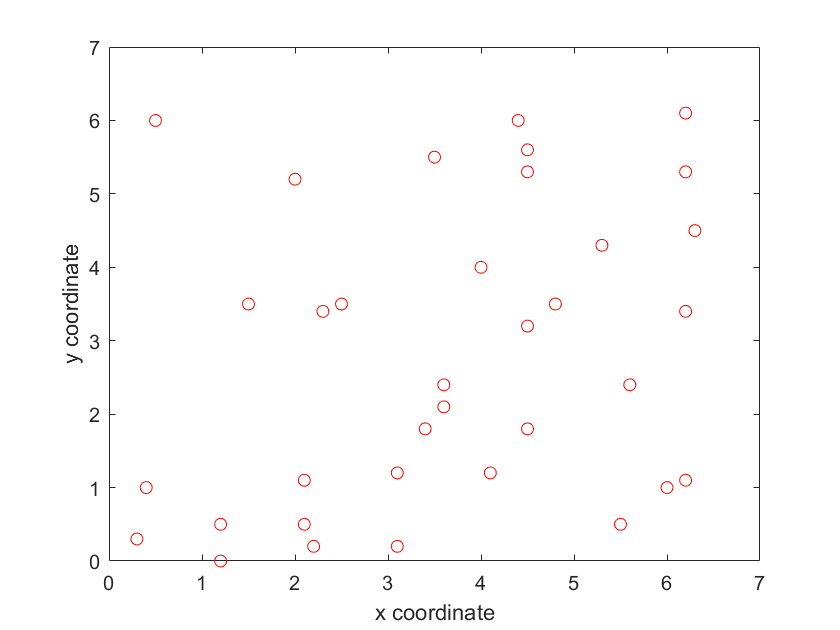

%plot the positions of the measured data points
plot(x,y,'or') 
xlabel('x coordinate') %label the x axis
ylabel('y coordinate') %label the y axis

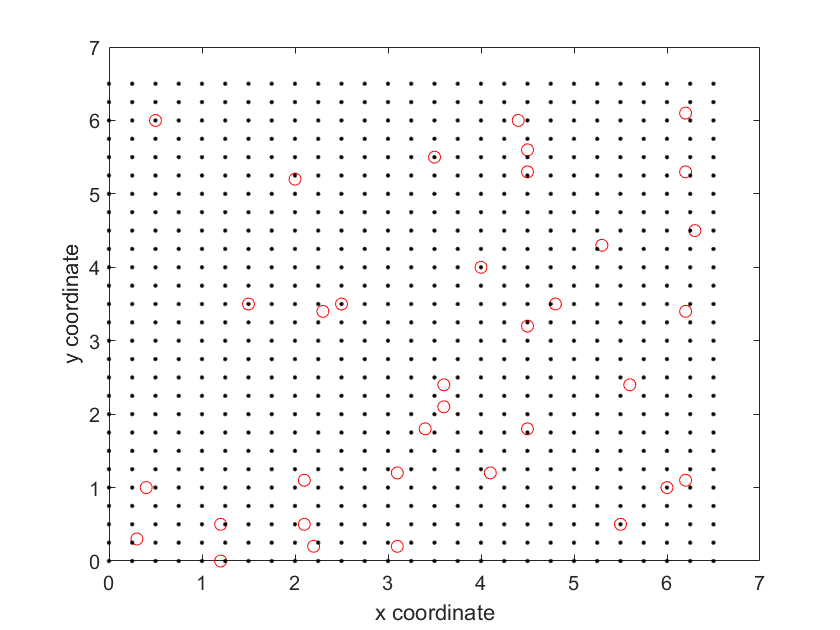

hold on
%equally spaced row vector of x positions
xi=[0:0.25:6.5]; 
%equally spaced column vector of y positions
yi=[0:0.25:6.5]; 
[xi_grid,yi_grid]=meshgrid(xi,yi);
plot(xi_grid,yi_grid,'.k') %plot the grid positions

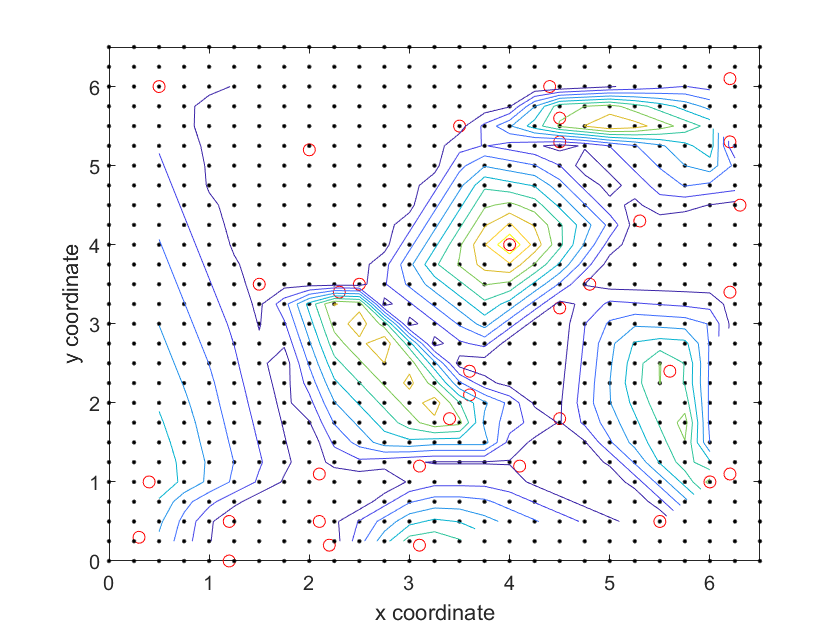

%interplolate values at grid point
%interpolate the z data
zi_grid=griddata(x,y,z,xi_grid,yi_grid); 
hold on
%plot 10 contour lines
contour(xi_grid,yi_grid,zi_grid,10) 

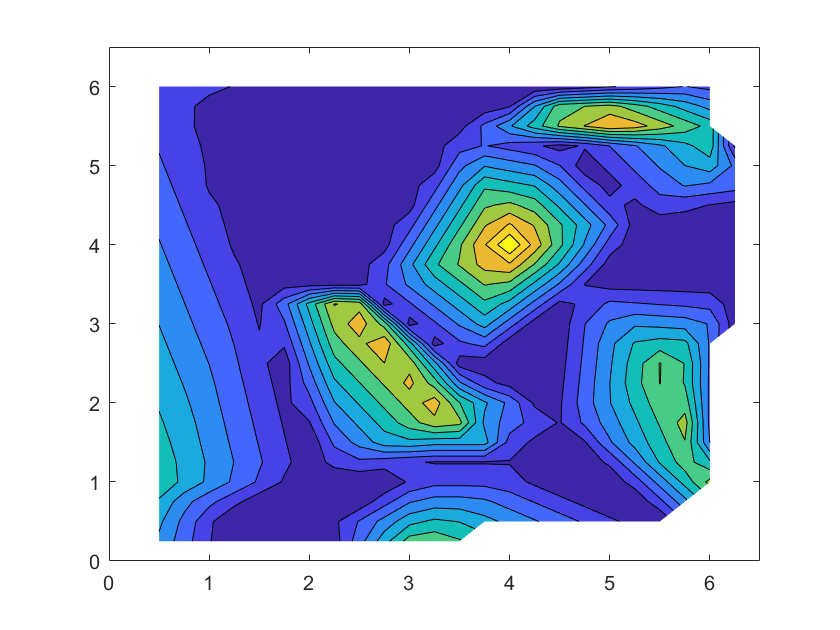

figure
%plot 10 filled contour intervals
contourf(xi_grid,yi_grid,zi_grid,10) 

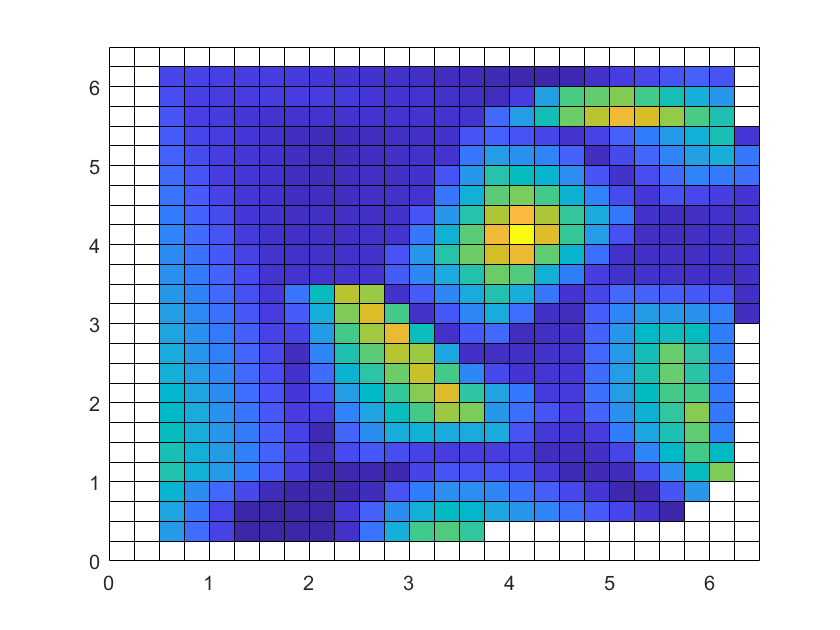

figure
pcolor(xi_grid,yi_grid,zi_grid) %pseudocolor plot

## II - Saving and exporting figures

## III - Example - Logistic Map

x=rand(1)

x = 0.8061

r=rand(1)*4

r = 0.5391


for i=1:2000
    x=r.*x*(1-x);
end

N=1e3 %total number of realizations

N = 1000

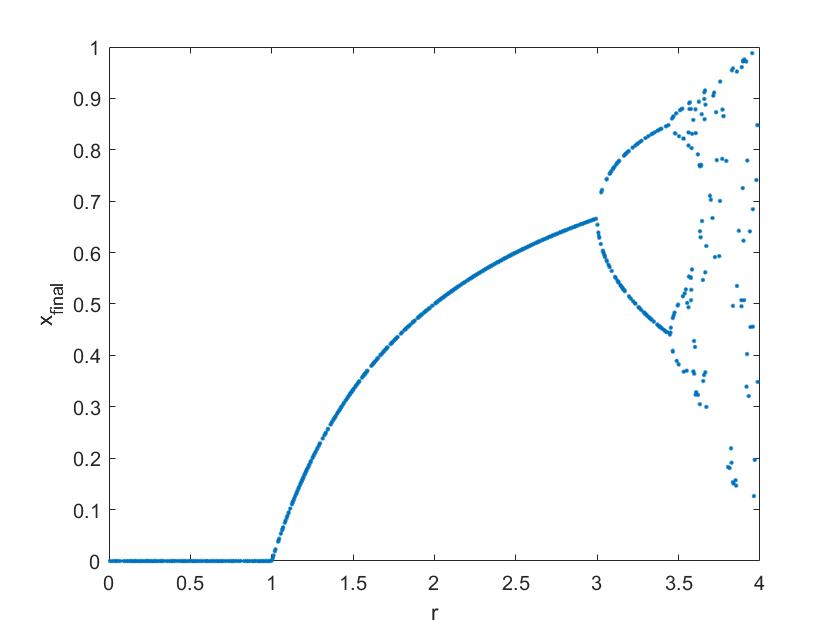

x=rand(N,1); %generate the initial populations
r=rand(N,1)*4; %generate the values of r
for j=1:N %loop through all the realizations
    for i=1:2000 %iterate the logistic equation
        %update the population
        x(j)=r(j).*x(j)*(1-x(j)); 
    end
end

% Finally we just need to plot the data and label 
% the axes:
plot(r,x,'.')
ylabel('x_{final}')
xlabel('r')